# Create and Customize Parallel Plots 

`parallelplot` creates parallel coordinate plots.

### Read Patients Data

We will use "`patients.mat" `to demonstrate how to create and customize parallel plots. The MAT-file contains various medical patient data of 100 patients.

load("patients.mat")

### Basic Parallel Plot

Create a table from a subset of the variables loaded into the workspace and create a parallel coordinates plot using the table. The lines in the plot correspond to individual patients and indicate that smokers tend to have higher blood pressure values (both diastolic and systolic).

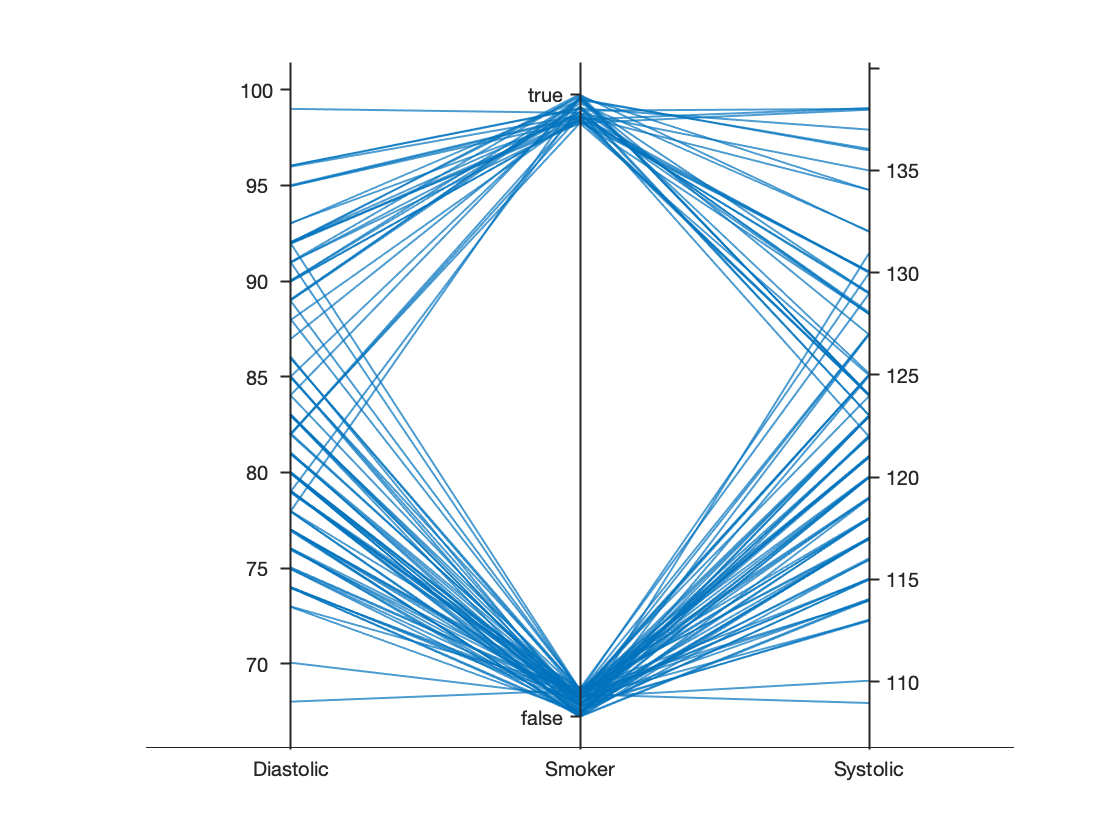

tbl= table(Diastolic,Smoker,Systolic);
parallelplot(tbl);

## Customization

### Group Variables

To distinguish groups of lines on a parallel plot, specify a *GroupVariable *that should be used when plotting using a table. This clearly distinguishes the Smoker group from the Non-Smoker group.

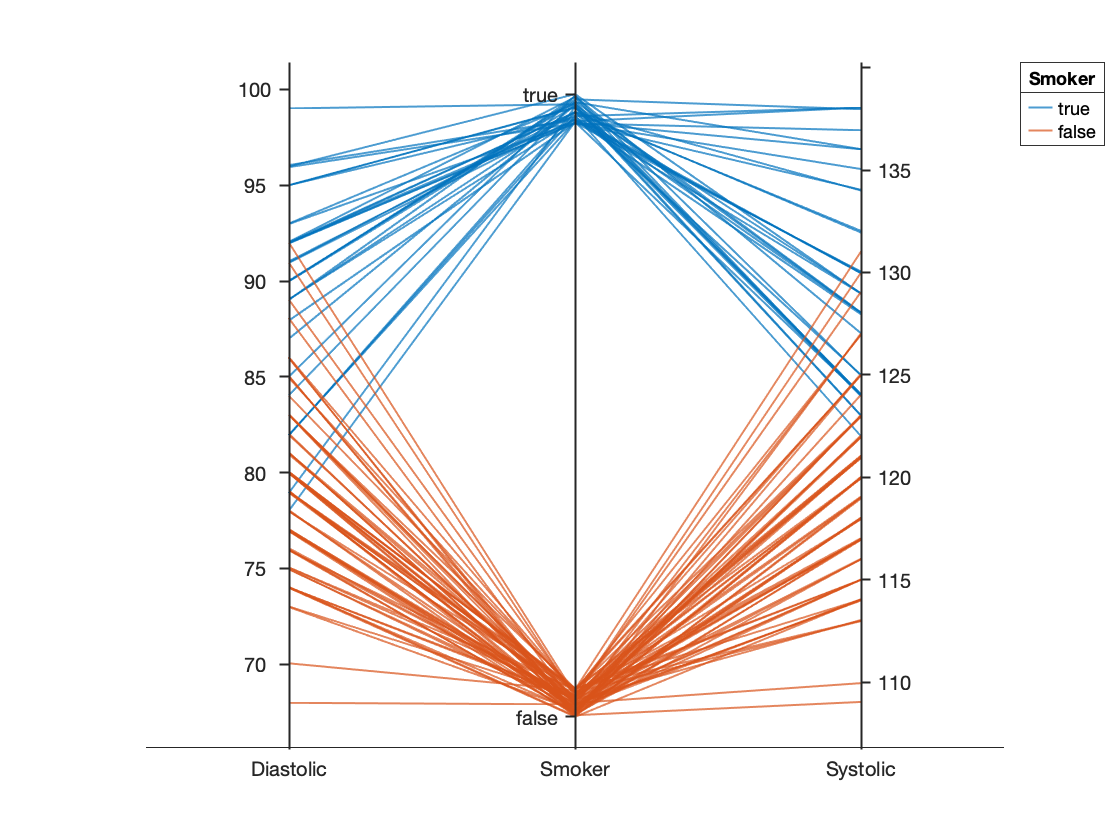

p = parallelplot(tbl,...
    "GroupVariable","Smoker");  % Specify Smoker as the GroupVariable

### Modify Jitter

Jittering is helpful for distinguish between plot lines more easily. For example, observe the plot lines along the `Smoker` coordinate ruler; the plot lines are not flush with either the `true` or `false` tick marks. To disable the default jittering, set the *Jitter* property to 0.

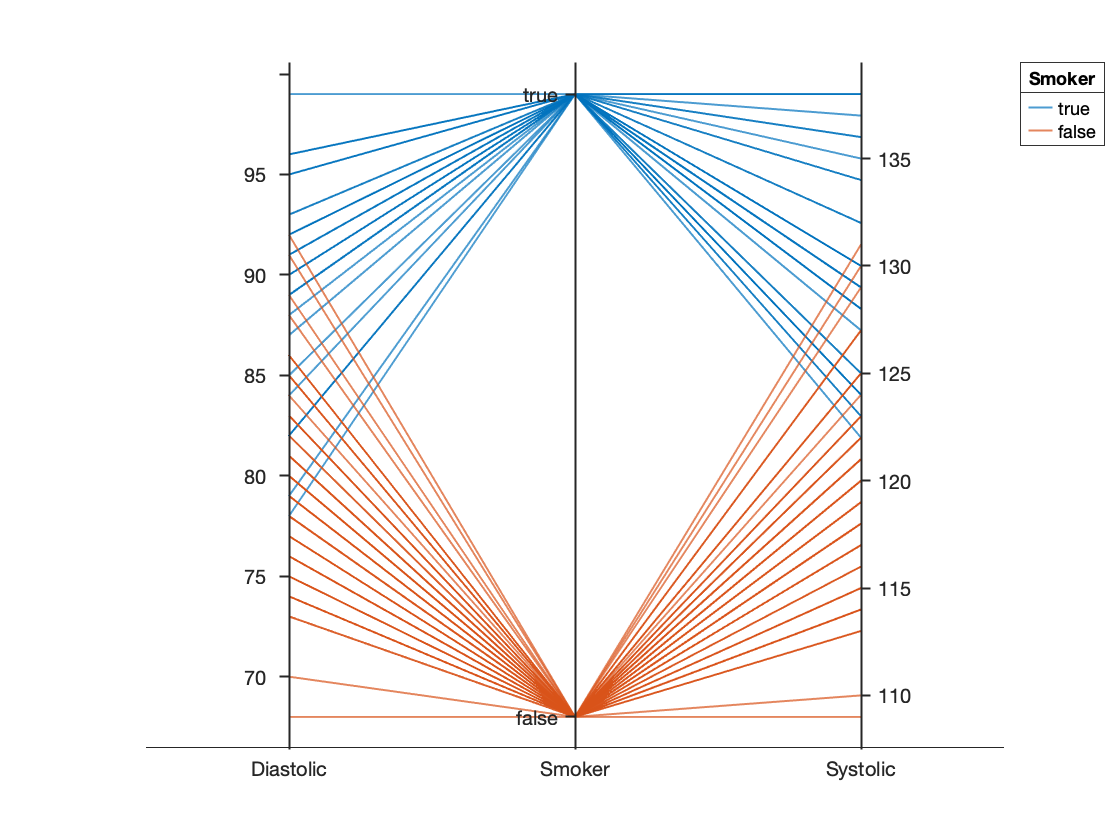

Jitter =0;

p1 = parallelplot(tbl,...
    "GroupVariable","Smoker",...
    "Jitter", Jitter);                   % Specify jitter between 0 and 1

### Modify Line Properties

The line properties can be changed by specifying the *Color* and *LineWidth* Name, Value pairs as arguments to `parallelplot`.

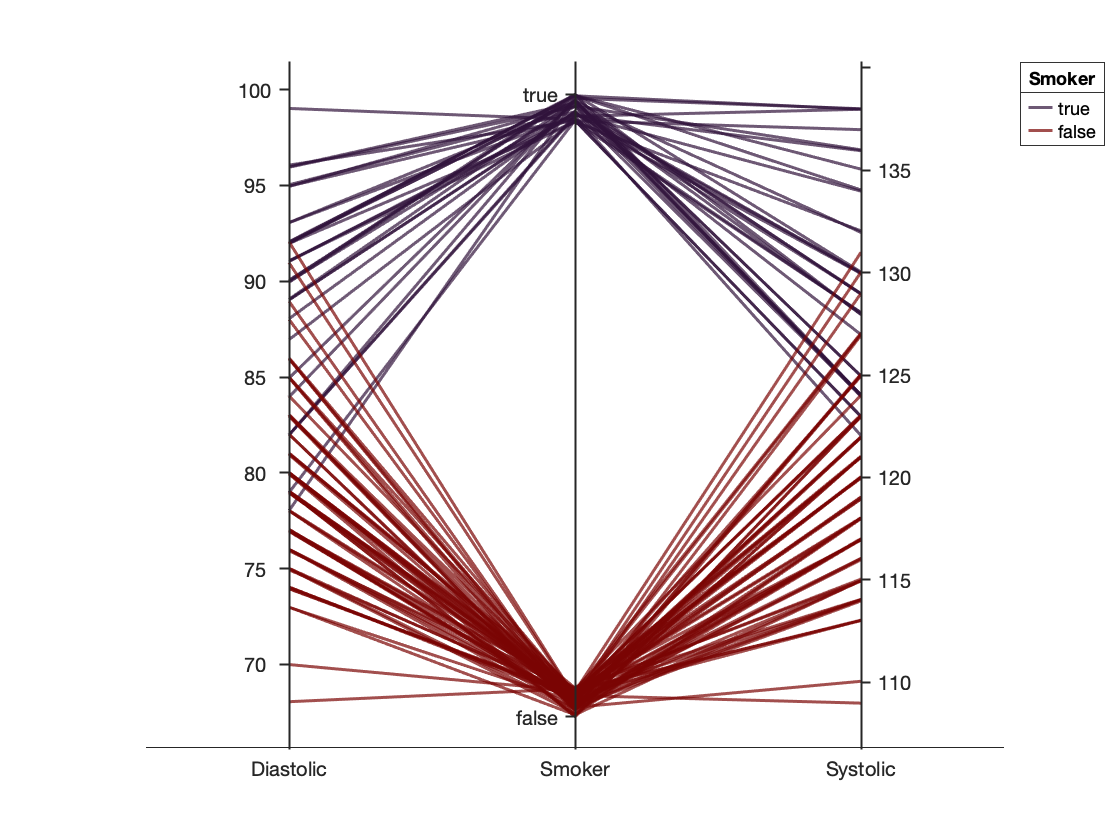

LineWidth = 1.5;

p2 = parallelplot(tbl,...
    "GroupVariable","Smoker",...
    "Color",turbo(2),...            % Specify colors from the turbo colormap
    "LineWidth",LineWidth);         % Specify the line width 

## **Additional Information**

### **Get All ParallelCoordinatesPlot Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a ParallelCoordinatesPlot, uncomment the following code. View or modify these properties using dot notation.

% get(p)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[parallelplot](https://www.mathworks.com/help/matlab/ref/parallelplot.html)

Copyright (c) 2021, The MathWorks, Inc.